# Sistemi Dinamici - Prova parziale 22/12/2023

**voto massimo: x punti**

Il voto finale sarà costituito dalla somma delle valutazioni conseguite nei due esercizi.

## Esercizio 2

Di un sistema dinamico lineare, tempo invariante, a tempo discreto, si conosce il modello in equazioni di stato 


$$\left\{
\begin{array}{rcl}
x_1(t+1)&=& x_2(t) +\eta_1(t) \\
x_2(t+1)&=& -\displaystyle \frac{1}{4} x_1(t) +\frac{1}{2} x_2(t) +\eta_2(t)\\
y(t)&=&  -\displaystyle \frac{1}{4} x_1(t) +\frac{1}{2} x_2(t) + \bar{b} + \epsilon(t)
\end{array}
\right. \qquad \Longleftrightarrow \qquad 
\begin{array}{l}
\eta_1(t),\,\eta_2(t) \;\mathrm{i.i.d.} \sim \mathrm{WNG}\left(0,\,10^{-2}\right) \\
\epsilon(t) \sim \mathrm{WNG}\left(0,\,10^{-1}\right)\\
\bar{b} \in \mathbb{R}
\end{array}$$


Lo stato del sistema non è accessibile, ma è misurabile l'uscita del sistema. Purtroppo il sensore di misura utilizzato per acquisire l'uscita è polarizzato, cioè fornisce un errore di misura che ha valore medio non nullo (valore medio $\bar b$  che ovviamente non è noto).

Sono a disposizione $4000$ osservazioni dell'uscita $y(t)$ del sistema. I dati sono a disposizione nel MAT-file "DATI_ESERCIZIO2_221223.MAT".

### Domanda 1

Si chiede di costruire un predittore di Kalman ad un passo in avanti che permetta di stimare contemporaneamente sia lo stato del sistema che il bias del sensore di misura $\bar b$.

### Suggerimento

Nel modello in equazioni di stato che utilizzerà il predittore di Kalman va inserita un'equazione che permetta di pensare alla costante incognita $\bar b$ come componente del vettore di stato...

### Domanda 2

È possibile implementare il predittore di Kalman a regime stazionario per il problema in questione? Motivare la risposta e nel caso sia possibile, confrontare i risultati con quelli del predittore ricorsivo.

### Caricamento dei dati

clear
close all
clc

load DATI_ESERCIZIO2_221223.MAT 

Fs = 1; % kHz
Ts = 1/Fs;

whos

  Name      Size              Bytes  Class     Attributes

  Fs        1x1                   8  double              
  Ts        1x1                   8  double              
  Y         1x4000            32000  double              



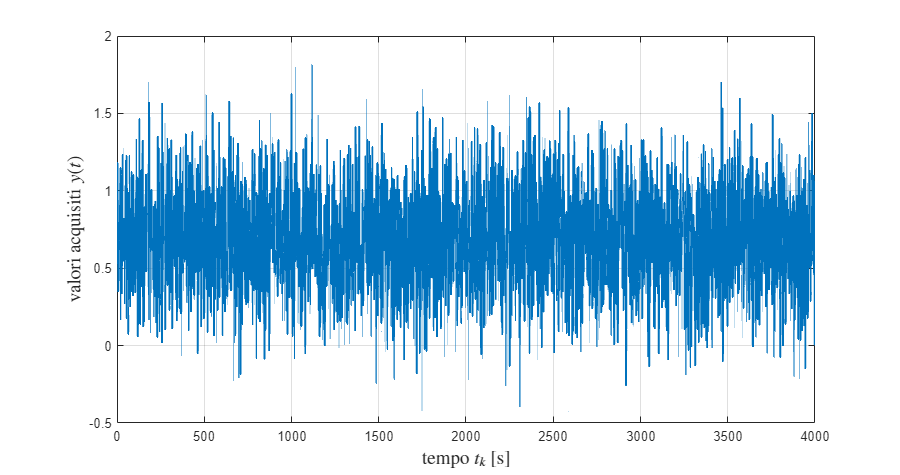


N1 = numel(Y);
t1 = (0:N1-1).*Ts; % istanti di tempo di campionamento

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.75]);
plot(t1, Y, 'LineWidth', 1.5);
grid on;
xlabel('tempo $t_k$ [s]','Interpreter','latex','FontSize',14);
ylabel('valori acquisiti $y(t)$','Interpreter','latex','FontSize',14);

### Domanda 1

Si chiede di costruire un predittore di Kalman ad un passo in avanti che permetta di stimare contemporaneamente sia lo stato del sistema che il bias del sensore di misura $\bar b$.

### Suggerimento

Nel modello in equazioni di stato che utilizzerà il predittore di Kalman va inserita un'equazione che permetta di pensare alla costante incognita $\bar b$ come componente del vettore di stato...


$$\left\{
\begin{array}{rcl}
x_1(t+1)&=& x_2(t) +\eta_1(t) \\
x_2(t+1)&=& -\displaystyle \frac{1}{4} x_1(t) +\frac{1}{2} x_2(t) +\eta_2(t)\\
y(t)&=&  -\displaystyle \frac{1}{4} x_1(t) +\frac{1}{2} x_2(t) + \bar{b} + \epsilon(t)
\end{array}
\right. \qquad \Longleftrightarrow \qquad 
\begin{array}{l}
\eta_1(t),\,\eta_2(t) \;\mathrm{i.i.d.} \sim \mathrm{WNG}\left(0,\,10^{-2}\right) \\
\epsilon(t) \sim \mathrm{WNG}\left(0,\,10^{-1}\right)\\
\bar{b} \in \mathbb{R}
\end{array}$$


We can treat $\bar{b}$ as a third state variable that is kept constant across time.

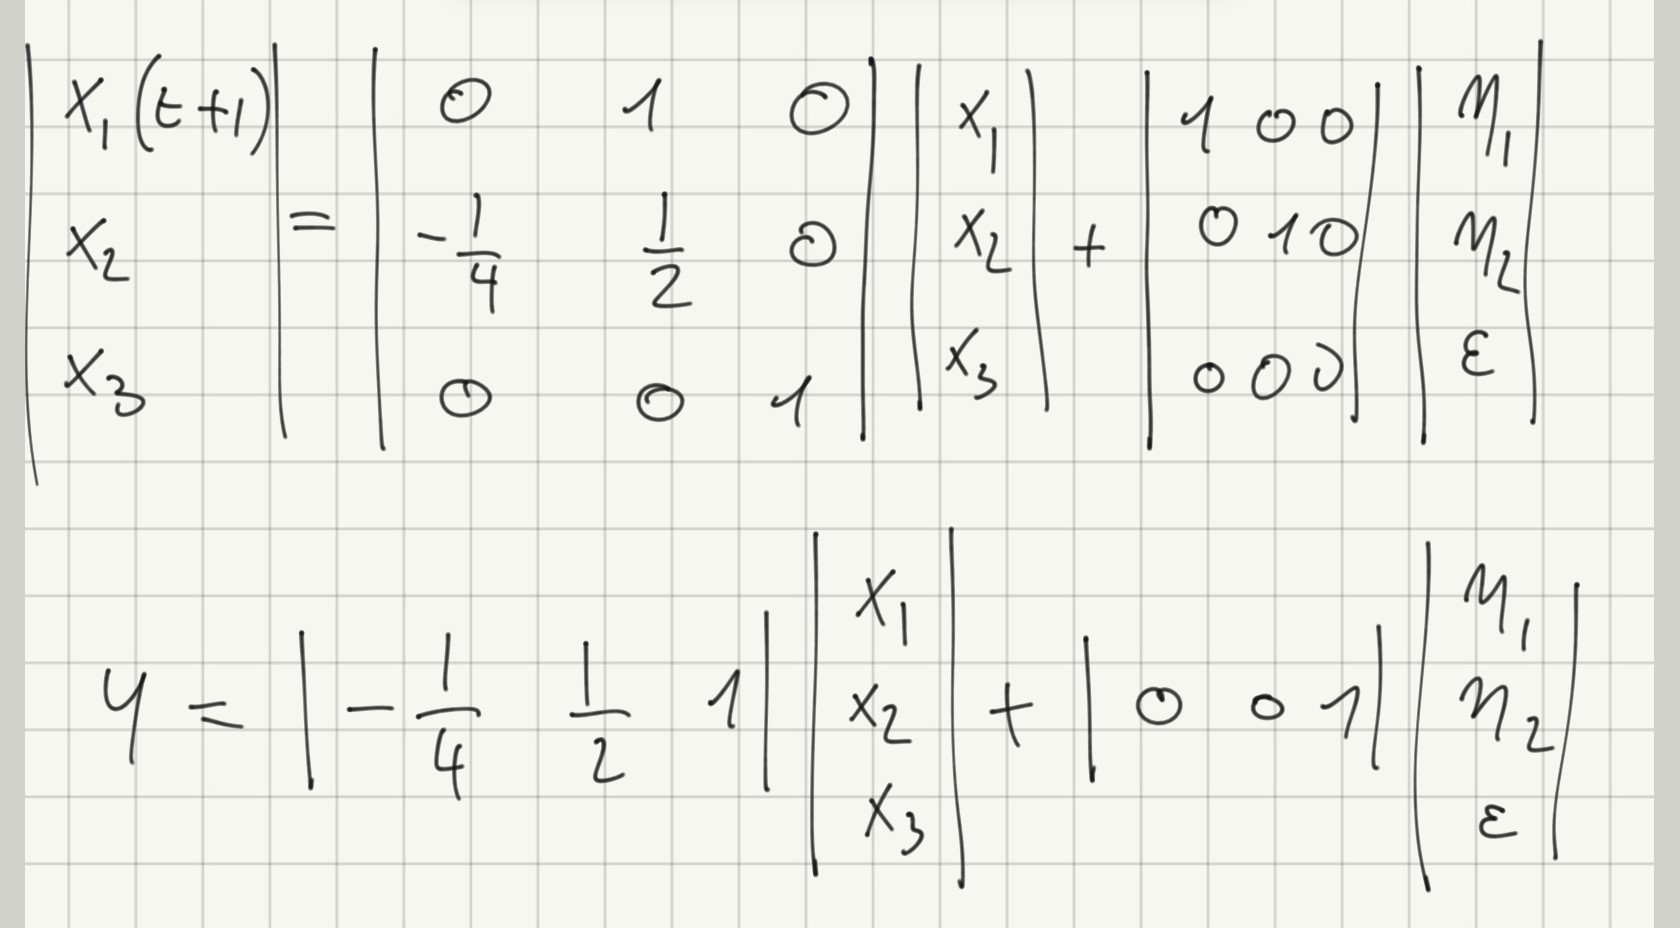

matA = [0 1 0; -1/4 1/2 0; 0 0 1];
matB = [0; 0; 0];
%[1 0 0; 0 1 0; 0 0 0]; % eta1, eta2, epsilon are three different input noises
matC = [-1/4 1/2 1];
matD = 0;
%[0 0 1];

#### Kalman estimation


$$\left\{
\begin{array}{rcl}
\hat x(t+1 \, \vert \, t) &=&
			F \, \hat x (t\, \vert \,t-1)+G\,u(t)
			+ K(t) \cdot \big(y(t)-H\,\hat x (t\, \vert \,t-1)-D\,u(t)\big)  \\
K(t) &=& F \cdot P(t) \cdot H^{\top}
			\left [
			H \cdot P(t) \cdot H^{\top} + V_2
			\right ]^{-1} \\ 
P(t+1) &=& F \, \left \{
			P(t) - P(t) H^{\top} \,
			\left [
			V_2 + H P(t) H^{\top}
			\right ]^{-1} \, H P(t)
			\right \} \, F^{\top} + V_1
\end{array}
\right.$$


N = numel(t1);
Nx = size(matA,1);
xhat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
% xhat(:,1) = x1; % 1st state a priori estimation

y = Y; % the measurements
e = zeros(size(y)); % innovation 

P = zeros(Nx,Nx,N);
P1 = diag([1e6;1e6;1e6]); % high variance for a priori estimation, since we can't make any assumption
P(:,:,1) = P1; % 1st P matrix
F = matA;
G = matB;
H = matC;
D = matD;

eta_1_STD = sqrt(10e-2);
eta_2_STD = sqrt(10e-2);
epsilon_STD = sqrt(10e-1);
eta_1 = eta_1_STD*randn(size(y));
eta_2 = eta_2_STD*randn(size(y));
epsilon = epsilon_STD*randn(size(y));
uU = 0;

V1 = diag([eta_1_STD.^2; eta_2_STD.^2; 0]);
V2 = [epsilon_STD.^2];

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - (H*xhat(:,k));
    cP = P(:,:,k);
    K = (F*cP*H')/(H*cP*H'+V2);
    xhat(:,k+1) = F*xhat(:,k) + K*e(:,k);
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F';
    if (k<N)
        P(:,:,k+1) = Pnew;
    end
    
end % for k 


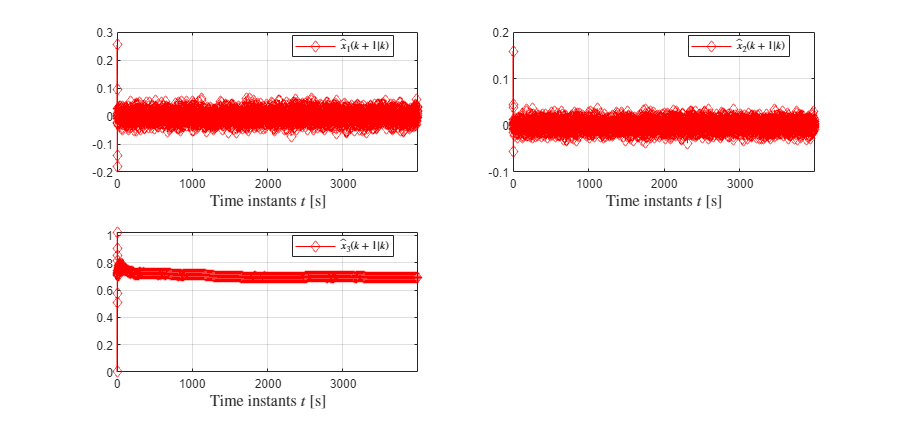

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
hp1 =subplot(2,2,1);
plot(t1,  xhat(1,:),'rd-')
grid on; zoom on;xlim([min(t1), max(t1)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('$\hat{x}_{1}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp2= subplot(2,2,2);
plot(t1,  xhat(2,:),'rd-');
grid on; zoom on;xlim([min(t1), max(t1)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('$\hat{x}_{2}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp3 = subplot(2,2,3);
plot(t1,  xhat(3,:),'rd-');
grid on; zoom on;xlim([min(t1), max(t1)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('$\hat{x}_{3}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

linkaxes([hp1, hp2, hp3], 'x')

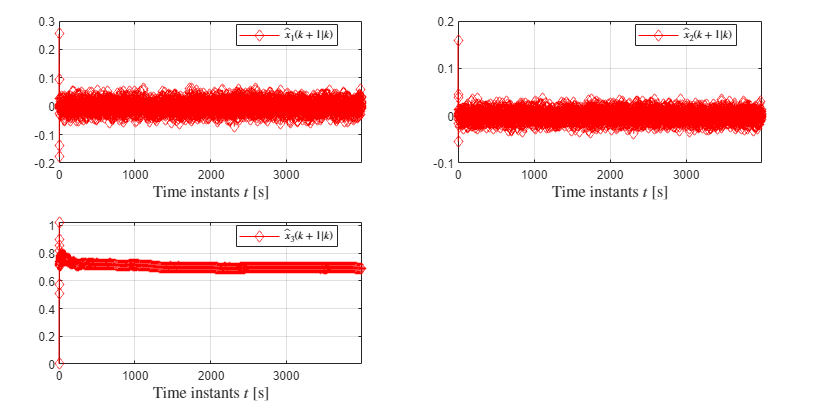

Since we don't know anything about the physical system we are examinating, it's hard to state any conclusion concerning the first two charts. What can be stated is that, since the model's equations are representing a non-unstable system, we are also seeing the same behavior by our estimation: the Kalmann predictor is not diveriging.

It's interesting to notice is that the third chart is converging towards a static value, which is accordant with the problem's statement: $\bar{b}$ is a constant value across time.

### Domanda 2

È possibile implementare il predittore di Kalman a regime stazionario per il problema in questione? Motivare la risposta e nel caso sia possibile, confrontare i risultati con quelli del predittore ricorsivo.

To check if it's possible to implement a steady-state kalman predictor, we have to check if the observability and reachability constraints are met.

obs_m = obsv(F,H); % returns observability matrix
isobs = length(F) - rank(obs_m) % if ZERO means is observable

isobs = 0


reach_m = ctrb(F,G); % returns reachability matrix
isreach = length(F) - rank(reach_m) % if ZERO means is reachable

isreach = 3

The **reachability check failed**, so **we can't calculate a steady-state Kalman predictor**. What happens if we try to calculate it anyway? In our case, the following code is failing, because of an error while calculating the inverse Reccati equation.

#### Solving the Algebraic Riccati Equation

P = zeros(Nx,Nx,10*N);
P(:,:,1) = P1; % 1st P matrix
for k = 1:(10*N-1)

    %e(:,k) = y(:,k) - (H*xhat(:,k)+D*uU(:,k));
    cP = P(:,:,k);
    K = (F*cP*H')/(H*cP*H'+V2);
    %xhat(:,k+1) = F*xhat(:,k) +G*uU(:,k)+ K*e(:,k);
    %xhat_r(:, k+r) = F^(r-1) * xhat(:,k+1);
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F';
    if (k<10*N)
        P(:,:,k+1) = Pnew;
    end

end % for k 
%disp(P(:,:,N));
disp(P(:,:,10*N));

    0.2309    0.0520   -0.0000
    0.0520    0.1337   -0.0000
   -0.0000   -0.0000    0.0000



[Pbar, Kbar]= idare(F', H', V1, V2)


Pbar =

     []


Kbar =

     []



So the steady-state predictor is

xxhat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
% xxhat(:,1) = x1; % 1st state a priori estimation

e = zeros(size(y)); % innovation 

%Pinf = Pbar;
Kbar = Kbar';

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - H*xxhat(:,k);
    
    
    xxhat(:,k+1) = F*xxhat(:,k) + Kbar*e(:,k);
    
    
end % for k 

Error using  + 
Arrays have incompatible sizes for this operation.

Related documentation